# Wykres wektorowy i linii prądu

Wykres wektorowy rysuje wektory zaczepione. Służy do wizualizacji pól wektorowych. Wykres linii prądu rysuje ruch cząsteczki poruszającej się w danym polu wektorowym.

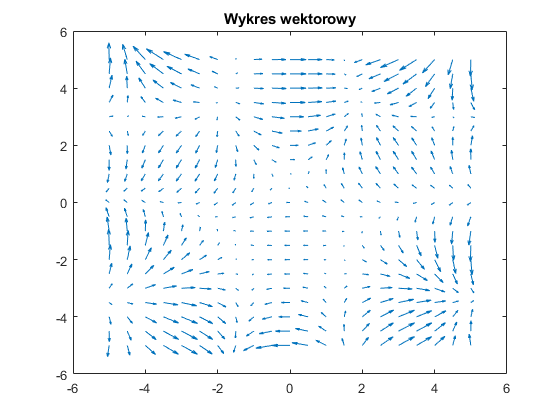

x = [-5:0.5:5];
y = [-5:0.5:5];
[X,Y] = meshgrid(x,y);
Z = Y.*sin(X) - X.*cos(Y);
[U,V] = gradient(Z);

quiver(X,Y,U,V)
title("Wykres wektorowy")

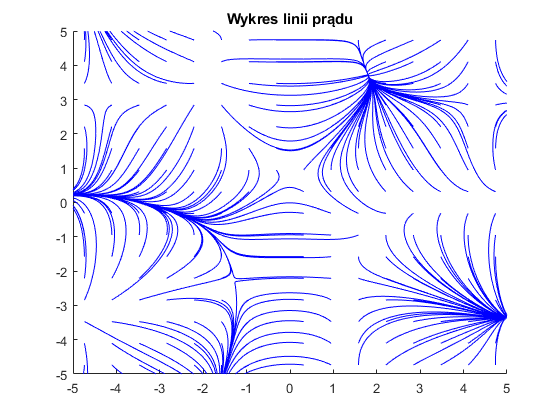

x = [-5:0.1:5];
y = [-5:0.1:5];
[X,Y] = meshgrid(x,y);
Z = Y.*sin(X) - X.*cos(Y);
[U,V] = gradient(Z);
sx = linspace(-6,6,20);
sy = linspace(-6,6,20);
[sx,sy] = meshgrid(sx,sy);
newplot()
streamline(X,Y,U,V,sx,sy)
title("Wykres linii prądu")

W poniższym przykładzie przedstawiono analizę graficzną powierzchni przedstawionej na poniższym wykresie

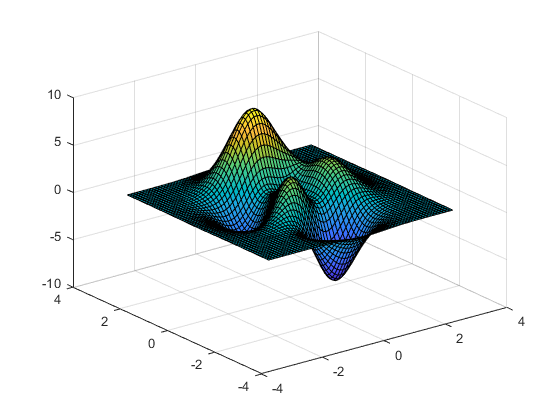

[x,y] = meshgrid(-3:0.1:3);
z = 3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2);
surf(x,y,z)

Określono jej warstwiece, gradient i wyznaczono linie prądu dla przeciwieństwa gradientu. Innymi słowy określono linie spływu.

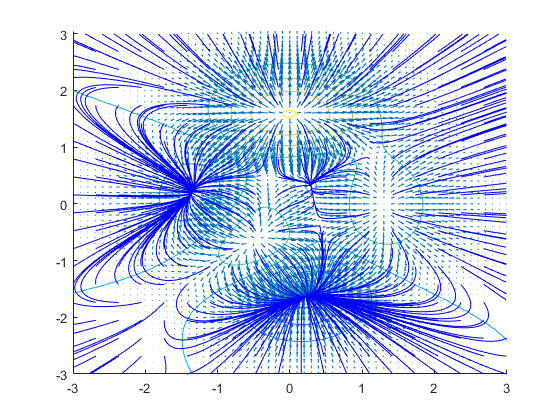

[u,v] = gradient(z);
sx = linspace(-3,3,20);
sy = linspace(-3,3,20);
[sx,sy] = meshgrid(sx,sy);
newplot()
hold on
contour(x,y,z)
quiver(x,y,-u,-v,3)
streamline(x,y,-u,-v,sx,sy)
hold off